% Define the data for lower limit, upper limit, and frequency
lowerLimits = [0,14,28,42,56,70,84,98,112,126]; 
upperLimits = [14,28,42,56,70,84,98,112,126,140]; 
frequencies = [7,10,12,15,12,16,18,19,25,42];  

% Create a table in MATLAB
dataTable = table(lowerLimits', upperLimits', frequencies',...
    'VariableNames', {'LowerLimit', 'UpperLimit', 'Frequency'});

% Display the table
disp(dataTable);

    LowerLimit    UpperLimit    Frequency
    __________    __________    _________

         0            14            7    
        14            28           10    
        28            42           12    
        42            56           15    
        56            70           12    
        70            84           16    
        84            98           18    
        98           112           19    
       112           126           25    
       126           140           42    




% Calculate mean, median, mode, and standard deviation
data = [];
for i = 1:length(lowerLimits)
    data = [data, ones(1, frequencies(i)) * ((upperLimits(i) + lowerLimits(i)) / 2)];
end

meanValue = mean(data);
medianValue = median(data);
modeValue = mode(data);
stdDeviation = std(data);

% Calculate empirical_mode, mode_shift, and Karl
empirical_mode = 3 * medianValue - 2 * meanValue;
mode_shift = modeValue - empirical_mode;
Karl = (meanValue - modeValue) / stdDeviation;

% Display the calculated statistics
fprintf('Mean: %.2f\n', meanValue);

Mean: 88.61


fprintf('Median: %.2f\n', medianValue);

Median: 91.00


fprintf('Mode: %.2f\n', modeValue);

Mode: 133.00


fprintf('Standard Deviation: %.2f\n', stdDeviation);

Standard Deviation: 39.38


fprintf('Empirical Mode: %.2f\n', empirical_mode);

Empirical Mode: 95.77


fprintf('Mode Shift: %.2f\n', mode_shift);

Mode Shift: 37.23


fprintf('Karl: %.2f\n', Karl);

Karl: -1.13


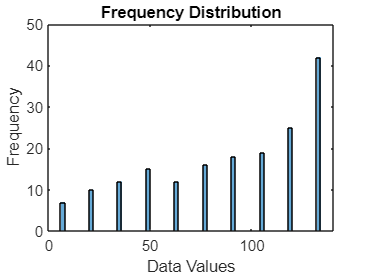


% Plotting the line graph
figure;
histogram(data, 'BinWidth', 2); % Change the 'BinWidth' according to your preference
title('Frequency Distribution');
xlabel('Data Values');
ylabel('Frequency');